**Công thức tính hàm gamma : **

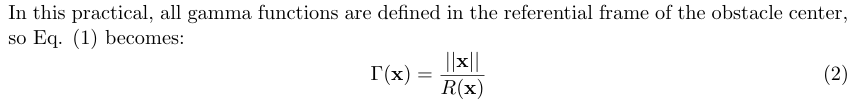

**Công thức tính gamma gradient : Đạo hàm của hàm gama.**

**TASK1: ** **Program the gamma function and its gradient for a vertical, infinite length cylinder.**

% function val = gamma(x,y,param) %do trục z vô hạn nên có thẻ bỏ z k dùng
% val=sqrt(x.^2+y.^2)/param.radius;
% end 
%cách viết khác
%gamma = @(x, y, z, param) sqrt(x.^2 + y.^2) / param.radius;
%gradientGamma = @(x, y, z, param) [x ./ (param.radius .* sqrt(x.^2 + y.^2)); y ./ (param.radius .* sqrt(x.^2 + y.^2));0.*z];
folder = fileparts(which('practical2_main.m'));
addpath(genpath(fullfile(folder, 'sources\library')));
%initialPosition = [0.6; 0.5; 0.0];
myworld = Environment([0.6; 0.5; 0.0]);

myworld.addCylinder(0.1, [-0.3, 0.45, 1]);
myworld.addEllipsoid([0.1,0.1, 0.1], [0.4, 0.2, 0.4]);

** TASK 2 Program the gamma function and its gradient for a 3D ellipsoid.**

% param = struct();
% param.ellipseAxes = axes; % [a; b; c]
% mu=@(x,y,z,param) 1 ./ sqrt((x ./ param.ellipseAxes(1)).^2 + (y ./ param.ellipseAxes(2)).^2 + (z ./ param.ellipseAxes(3)).^2 );
% gamma=@(x,y,z,param) 1./mu(x,y,z,param);
% gradientGamma = @(x, y, z, param) [x ./ (param.ellipseAxes(1).^2).* gamma(x, y, z, param);... 
% y ./ (param.ellipseAxes(2).^2) .* gamma(x, y, z, param);...
% z ./ (param.ellipseAxes(3).^2) .* gamma(x, y, z, param)];


**TASK3 **

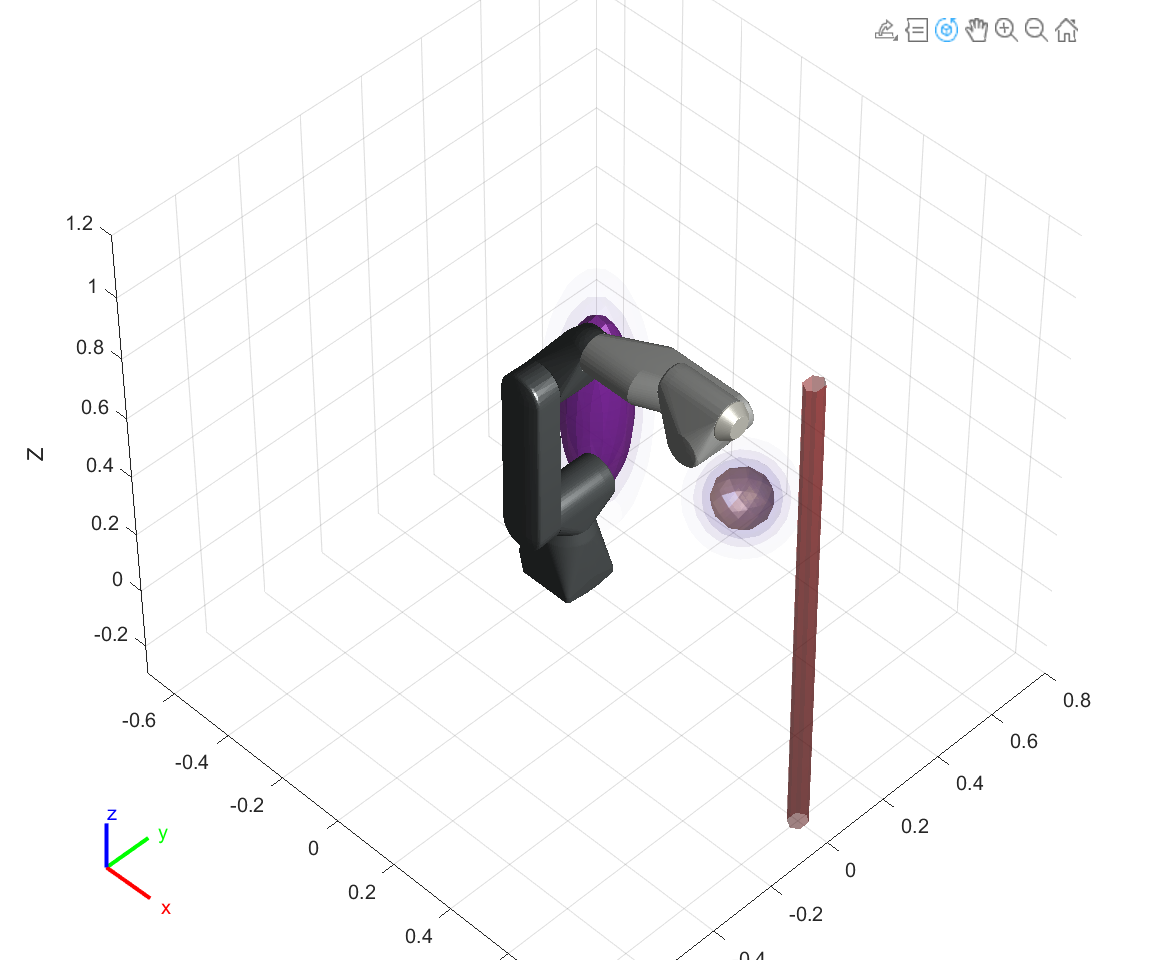

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%   Copyright (C) 2024 Learning Algorithms and Systems Laboratory, EPFL,
%    Switzerland
%   Author: Aude Billard
%   email: aude.billard@epfl.ch
%   website: lasa.epfl.ch
%    
%   Permission is granted to copy, distribute, and/or modify this program
%   under the terms of the GNU General Public License, version 3 or any
%   later version published by the Free Software Foundation.
%
%   This program is distributed in the hope that it will be useful, but
%   WITHOUT ANY WARRANTY; without even the implied warranty of
%   MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU General
%   Public License for more details
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Section 1: Create world and define obstacles
clc; clear; close all;
folder = fileparts(which('practical2_main.m'));
addpath(genpath(fullfile(folder, 'sources\library')));

initialPosition = [0;0;0];
myWorld = Environment(initialPosition); % Tạo môi trường bằng file enviroment 

% % Define a constant velocity in Z axis
% vel_func = @(x,t) [0; 1; 0];
% 
% % Define the obstacle velocity as a DS
%vel_func_2 = @(x,t) (A_obs * x + b_obs);
% 
% % Define a time-varying velocity vector
% vel_func_3 = @(x,t) [2*cos(50*t); 0; 0 ];

%==== TASK 1: ONE cylinder====
% Create a cylinder with a radius of 0.2m and a position
% in the X-Y plane of [-0.4, -0.4]:
%myWorld.addCylinder(0.1, [-0.3, .45, 1]);
%myWorld.addCylinder(0.1, [0.4, .45, 1]);

% ==== TASK 2: ONE ELLIPSOID ====
% myWorld.addEllipsoid([0.1, 0.1, 0.2], [0.3, 0.2, 0.5]);

% Create a sphere of radius 10cm with default rho value of 1.

myWorld.addEllipsoid([0.1, 0.1, 0.1], [0.4, 0.2, 0.4]);
%myWorld.showGammaIsosurfaces([1, 2, 4], true, [1 0 0]);
%→ Vẽ 3 isosurface gammaDistance tại mức 1,2,4 bằng màu đỏ.
%myWorld.showGammaIsosurfaces([1, 2, 5]);

% Create the same sphere with a rho value of 0.5

myWorld.addEllipsoid([0.1, 0.1, 0.3], [-0.3, 0.4, 0.1]);

% Create a sphere with 10cm radius at the origin, a rho value of 0.5, ...and a velocity function
%myWorld.addEllipsoid([0.1, 0.1, 0.1], [0.1, -0.5, 0.3], 1, vel_func);

% % ==== TASK 3.1: ONE ELLIPSOID ====
%myWorld.addEllipsoid([0.1, 0.2, 0.3], [0.0, 0.0, 0.0]);
isoGamma = [0.8 1.0 1.2 1.5];
myWorld.showGammaIsosurfaces(isoGamma, 0);   % 0 = dung gamma
% 
% % ==== TASK 3.2: ADD A CYLINDER ====
myWorld.addCylinder(0.030, [0.8, 0.0, 0.0]);   % r = 0.30 m

% myWorld.showGammaIsosurfaces(isoGamma, 0);    % dung gamma
% 
% % ==== TASK 3.3: USE gammaDistance (PHYSICAL DISTANCE) ====
% isoDist = [-0.10 0 0.10 0.30];        % m
 %myWorld.showGammaIsosurfaces(isoDist, 1);     % 1 = dung gammaDistance

% Section 2: Simulate initial conditions

% Initial state: joint velocity and position
q = myWorld.robot.computeInverseKinematics(initialPosition, myWorld.robot.robot.homeConfiguration,false);
q_dot = zeros(length(q), 1);